Kryterium koła i twierdzenie Popova

Zadanie 5.1

%G(s) = 4(1-5s) / (1+3s)(1+2s)
%licz = 4(1-5s)= 4-20s
%mian = (1+3s)(1+2s) = 1+2s+3s+6s^2 = 6s^2+ + 5s + 1
clear all;
close all;
licz = [-20 4];
licz_minus = [-1 2]

licz_minus =     -1     2


mian = [1 4 6 4 1];
G_minus = tf(licz_minus, mian)

G_minus =
 
             -s + 2
  -----------------------------
  s^4 + 4 s^3 + 6 s^2 + 4 s + 1
 
Continuous-time transfer function.
Model Properties


[P,Q,w] = nyquist(licz_minus, mian);

%P = nyquistoptions;
%P.ShowFullContour = 'off';
%nyquist(G,P)

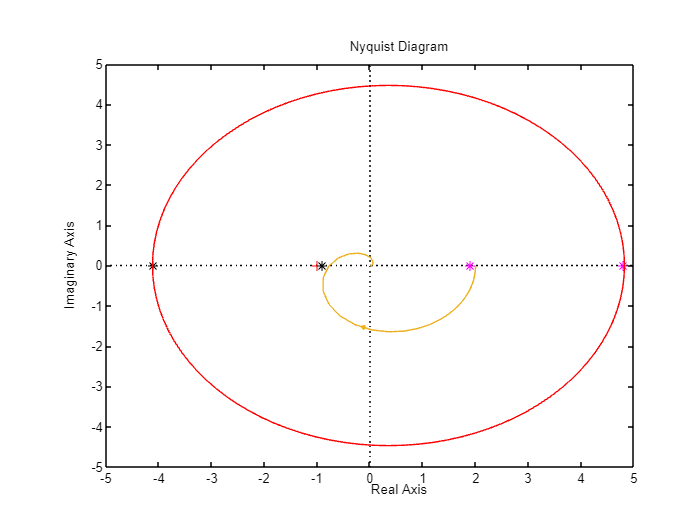

m1 = -0.9^(-1); %juz przekształcone parametry
m2 = 1.9^(-1);
hold on
P = nyquistoptions;
P.ShowFullContour = 'off';
nyquist(G_minus,P)
plot(1/m1, 0, 'k*')
plot(1/m2, 0, 'm*')
xlim([-5 5])
ylim([-5 5])

saveas(gcf,'1.png')

m1 = -0.9^(-1) %juz przekształcone parametry

m1 = -1.1111

m2 = 1.9^(-1)

m2 = 0.5263


[A,b,c,d] = tf2ss(licz_minus,mian);
A

A =     -4    -6    -4    -1
     1     0     0     0
     0     1     0     0
     0     0     1     0


b

b =      1
     0
     0
     0


c

c =      0     0    -1     2


m0 = 0.5;

macierz = A+b*m0*c

macierz =    -4.0000   -6.0000   -4.5000         0
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


wlasne = eig(macierz)

wlasne =    0.0000 + 0.0000i
  -2.2041 + 0.0000i
  -0.8980 + 1.1115i
  -0.8980 - 1.1115i


if length(wlasne > 0) == 2
    disp(['Dla m0 równego ', num2str(m0), ' macierz jest asymptotycznie stabilna'])
end

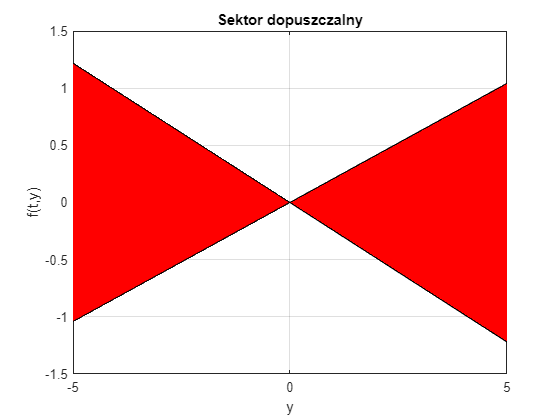

x = -5:0.01:5;
y1 = m1*x;
plot(x,y1);
hold on
y2 = m2*x;
plot(x,y2);
%dwie proste dla odpowiednich m
grid on;
area(x,y1, 'FaceColor', 'r'); % 'LineStyle', ':'
area(x,y2, 'FaceColor', 'r');
title('Sektor dopuszczalny')
xlabel('y');
ylabel('f(t,y)');
saveas(gcf,'2.png')

%POPOV 
close all;
Licz=[20 -4]; %ujemna transmitancja wprowadzona
Mian=[6 5 1];
w = 0:0.001:100;
[P,Q,w]=nyquist(Licz, Mian, w);

[A,B,c,d] = tf2ss(licz_minus,mian)

A =    -0.8333   -0.1667
    1.0000         0


B =      1
     0


c =     3.3333   -0.6667


d = 0

wlasne = eig(A)

wlasne =    -0.5000
   -0.3333


plot(P, w.*Q,'b');
grid on;
hold on;
a = 1.494

a = 1.4940

b = -5.99

b = -5.9900

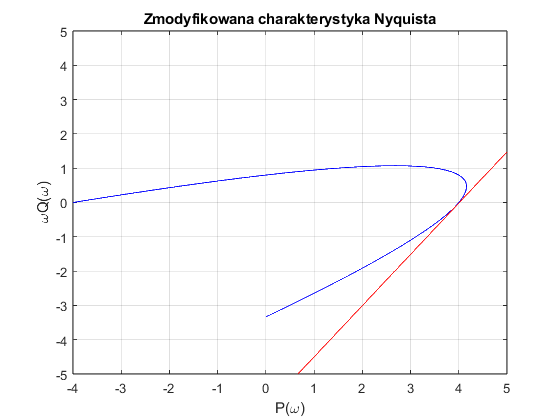

x = -3:0.01:5;
y = a*x+b;
plot(x,y,'r');
title('Zmodyfikowana charakterystyka Nyquista');
xlabel('P(\omega)');
ylabel('\omegaQ(\omega)');
ylim([-5 5])
saveas(gcf,'3.png')

close all;
%m = 0.25
m = 1/(-b / a)

m = 0.2494

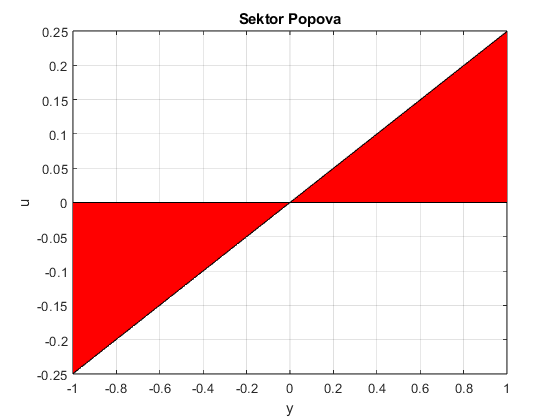

x = -1:0.01:1;
y1 = m*x;
plot(x,y1);
hold on
a = 0;
y2 = a*x;
plot(x,y2);
area(x,y1, 'FaceColor', 'r');
area(x,y2, 'FaceColor', 'r');

%dwie proste dla m=0 i m=0.25
xlabel('y');
ylabel('u');
grid on;
title('Sektor Popova')
saveas(gcf,'4.png')

%Zadanie 5.2
A = [-2 1 0;-1 0 1;-1 0 0]

A =     -2     1     0
    -1     0     1
    -1     0     0


b = [-1; 0; 0]

b =     -1
     0
     0


c = [1 0 0]

c =      1     0     0


d = [0]

d = 0

eig(A)

ans =   -1.7549 + 0.0000i
  -0.1226 + 0.7449i
  -0.1226 - 0.7449i


mm = length(eig(A)>0); %badanie stabilności macierzy A
if mm == 3
    disp(['Macierz A jest asymptotycznie stabilna'])
end

Macierz A jest asymptotycznie stabilna


[Licz Mian] = ss2tf(A,b,c,d)

Licz =      0    -1     0     0


Mian =     1.0000    2.0000    1.0000    1.0000


w = 0:0.001:100;

[P,Q,w] = nyquist(Licz,Mian,w);

close all;
G_minus = tf(Licz, Mian)

G_minus =
 
         -s^2
  -------------------
  s^3 + 2 s^2 + s + 1
 
Continuous-time transfer function.



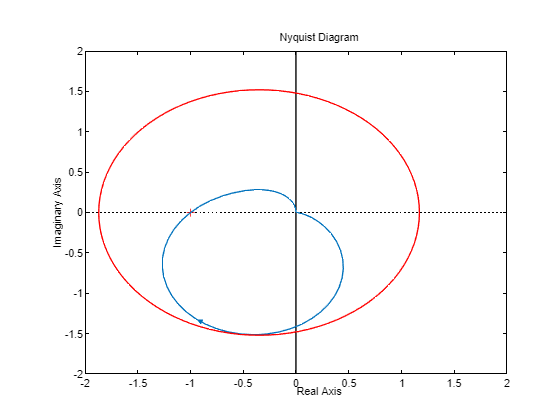

P = nyquistoptions;
P.ShowFullContour = 'off';
nyquist(G_minus,P)
xlim([-2 2])
ylim([-2 2])
circle(-0.35,0,1.52);
saveas(gcf,'5.png')

%ginput
m1 = -1.914^(-1); %juz przekształcone parametry
m2 = 1.114^(-1);
%moje
m1 = -1.87^(-1) %juz przekształcone parametry

m1 = -0.5348

m2 = 1.17^(-1)

m2 = 0.8547


m0 = 0.5;

macierz = A+b*m0*c;
wlasne = eig(macierz);
if length(wlasne > 0) == 3
    disp(['Dla m0 równego ', num2str(m0), ' macierz jest asymptotycznie stabilna'])
end

Dla m0 równego 0.5 macierz jest asymptotycznie stabilna


x = -2:0.1:2;
y1 = m1*x;
plot(x,y1);
hold on
y2 = m2*x;
plot(x,y2);
MM = 0.85

MM = 0.8500

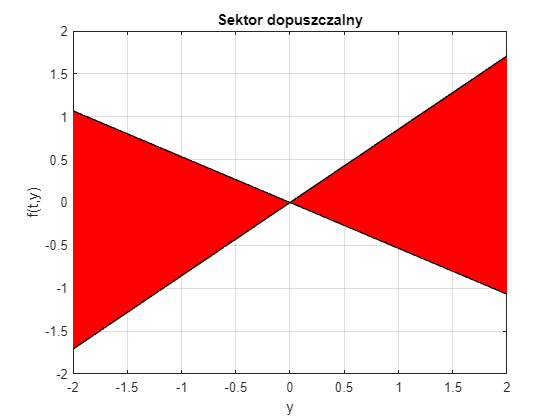

y4 = MM * atan(x);


grid on;
area(x,y1, 'FaceColor', 'r'); % 'LineStyle', ':'
area(x,y2, 'FaceColor', 'r');
%plot(x, y4, 'b-', 'LineWidth',2)
title('Sektor dopuszczalny')
xlabel('y');
ylabel('f(t,y)');
saveas(gcf,'6.png')

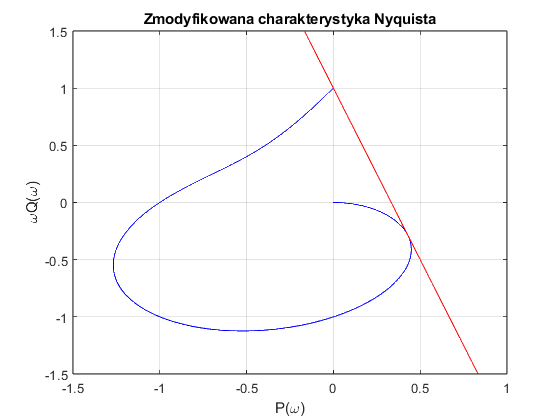

close all;
[P,Q,w] = nyquist(Licz,Mian,w);
plot(P,w.*Q,'b');
grid on;
hold on;
aa = -3;
bb = 1;
x = -1.3:0.01:1;
y = aa*x+bb;
plot(x,y,'r');
title('Zmodyfikowana charakterystyka Nyquista');
xlabel('P(\omega)');
ylabel('\omegaQ(\omega)');
axis([-1.5 1 -1.5 1.5]);
saveas(gcf,'7.png')

close all;
m = 1/(1/3)

m = 3

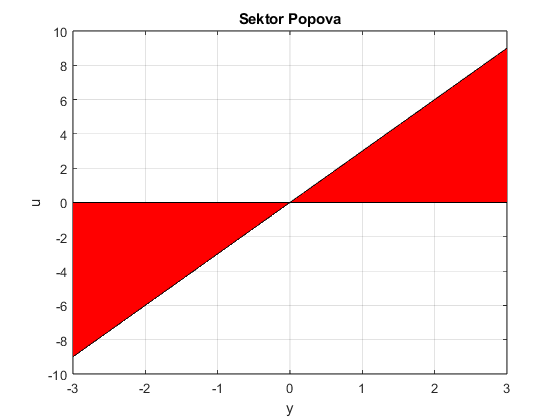


x = -3:0.01:3;
y1 = m*x;
plot(x,y1);
hold on
aaa = 0;
y2 = aaa*x;
plot(x,y2);
area(x,y1, 'FaceColor', 'r');
area(x,y2, 'FaceColor', 'r');

MM = 3;
%hold on
%y4 = MM * atan(x);
%plot(x,y4,'b-', 'LineWidth',2)


title('Sektor Popova')

xlabel('y');
ylabel('u');
grid on;
saveas(gcf,'8.png')

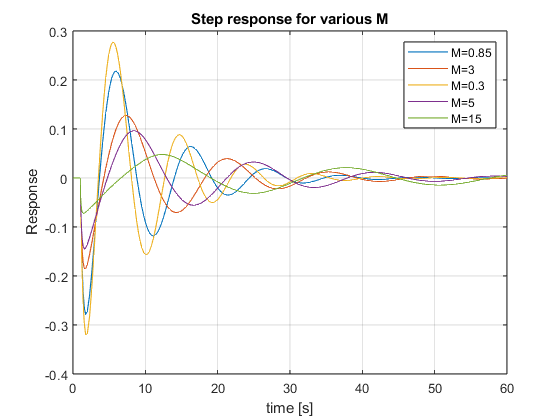

close all;
plot(tout, step)
hold on
plot(tout, step1)
plot(tout, step2)
plot(tout, step3)
plot(tout, step4)
legend("M=0.85", "M=3","M=0.3","M=5","M=15")
hold off
xlabel("time [s]")
ylabel("Response")
title("Step response for various M")
grid on
saveas(gcf,'9.png')

function h = circle(x,y,r)
hold on
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit, 'r-');
hold off
end